# Modelo de Calcio VS Infección con VPH variable

**Observación:** Comportamiento extraño para VPH entre 4.6 y 5.3.

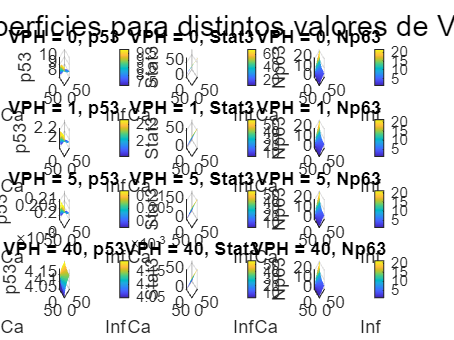

% Preparación del entorno
clear;
clc;
close all;

% Definición simbólica del sistema
syms p53 Stat3 Np63 Ca1 Ca2 Inf VPH

% Parámetros fijos
Pp53 = 1.1380;
N = 0.6184;
k = 1.8558;
B = 1.6019;
ANp63p53 = 1.3864;
C1 = 0.8905;
dNp63p53 = 1.0944;
Dp53 = 0.1597;
Pstat3 = 0.9819;
ANp63s = 0.0053;
Ap53s = 1.1090;
Dstat3 = 0.8895;
PNp63 = 5.7201;
Astat3Np = 0.9350;
C2 = 1.2659;
dp53NP = 0.0000;
C3 = 2.8150;
dNp63Np63 = 0.2113;
DNp63 = 3.3663;

% Ecuaciones del sistema
f1 = (Pp53 + B*(p53^N)/(k^N + p53^N) + ANp63p53*Np63) * C1/(1 + dNp63p53*Np63) * 1/(1+VPH) - Dp53*(1+VPH)*p53;
f2 = (Pstat3*Ca1 + ANp63s*Np63 + Ap53s*p53) - Dstat3*Stat3;
f3 = (PNp63*Inf + Astat3Np*Stat3) * C2/(1 + dp53NP*p53) * C3/(1 + dNp63Np63*Np63) - DNp63*Np63*Ca2;

vars = [p53, Stat3, Np63];

% Grilla de parámetros
nPerAxis = 20;
Ca_vals = linspace(0, 50, nPerAxis);
Inf_vals = linspace(0, 50, nPerAxis);
[Ca_grid, Inf_grid] = meshgrid(Ca_vals, Inf_vals);

Ca_list = Ca_grid(:);
Inf_list = Inf_grid(:);
nSamples = numel(Ca_list);

% Valores del parámetro VPH
VPH_vals = [0, 1, 5, 40];
nConstantes = length(VPH_vals);

% Inicializar almacenamiento de resultados
p53_grids = cell(nConstantes, 1);
Stat3_grids = cell(nConstantes, 1);
Np63_grids = cell(nConstantes, 1);

% Paso principal: resolución por cada valor de Constante
for c = 1:nConstantes
    Cval = VPH_vals(c);
    resultados = [];

    for i = 1:nSamples
        val_Ca = Ca_list(i);
        val_Inf = Inf_list(i);

        eqs = [
            subs(f1, [Ca1, Ca2, Inf, VPH], [val_Ca, val_Ca, val_Inf, Cval]) == 0;
            subs(f2, [Ca1, Ca2, Inf], [val_Ca, val_Ca, val_Inf]) == 0;
            subs(f3, [Ca1, Ca2, Inf], [val_Ca, val_Ca, val_Inf]) == 0
        ];

        sol = vpasolve(eqs, vars);
        x1 = double(sol.p53);
        x2 = double(sol.Stat3);
        x3 = double(sol.Np63);

        if all(isreal([x1 x2 x3])) && all([x1 x2 x3] >= 0)
            resultados = [resultados; val_Ca, val_Inf, Cval, x1, x2, x3];
        end
    end

    % Crear grillas
    p53_grid = NaN(nPerAxis, nPerAxis);
    Stat3_grid = NaN(nPerAxis, nPerAxis);
    Np63_grid = NaN(nPerAxis, nPerAxis);

    for i = 1:nPerAxis
        for j = 1:nPerAxis
            val_Ca = Ca_vals(j);
            val_Inf = Inf_vals(i);

            idx = find(abs(resultados(:,1) - val_Ca) < 1e-3 & abs(resultados(:,2) - val_Inf) < 1e-3);
            if ~isempty(idx)
                p53_grid(i,j) = resultados(idx(1),4);
                Stat3_grid(i,j) = resultados(idx(1),5);
                Np63_grid(i,j) = resultados(idx(1),6);
            end
        end
    end

    % Guardar
    p53_grids{c} = p53_grid;
    Stat3_grids{c} = Stat3_grid;
    Np63_grids{c} = Np63_grid;
end

% Paso final: graficar en matriz de subplots
varNames = {'p53', 'Stat3', 'Np63'};
grids = {p53_grids, Stat3_grids, Np63_grids};

figure;
for c = 1:nConstantes
    for v = 1:3
        subplot(nConstantes, 3, (c-1)*3 + v);
        surf(Ca_grid, Inf_grid, grids{v}{c}, 'EdgeColor', 'none');
        view(45, 30);
        colorbar;
        xlabel('Ca'); ylabel('Inf'); zlabel(varNames{v});
        title(['VPH = ' num2str(VPH_vals(c)) ', ' varNames{v}]);
    end
end
sgtitle('Superficies para distintos valores de VPH');

## Coordenada p53

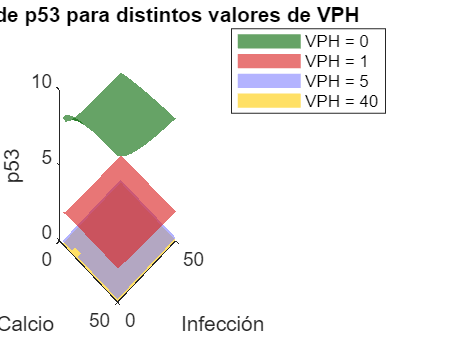

figure;
hold on;

colores = [0 0.4 0; 0.85 0.1 0.1; 0.5 0.5 1; 1 0.8 0];
leyendas = {'VPH = 0', 'VPH = 1', 'VPH = 5', 'VPH = 40'}; % ajusta si usas otros valores
h = gobjects(4,1); % para almacenar los handles
for k = 1:4
    h(k) = surf(Ca_grid, Inf_grid, grids{1}{k}, ...
                'EdgeColor', 'none', ...
                'FaceColor', colores(k,:), ...
                'FaceAlpha', 0.6);
end

view(45, 30);
xlabel('Calcio'); ylabel('Infección'); zlabel('p53');
title('Superficies de p53 para distintos valores de VPH');
legend(h, leyendas, 'Location', 'northeastoutside'); % leyenda externa al gráfico

## Coordenada Stat3

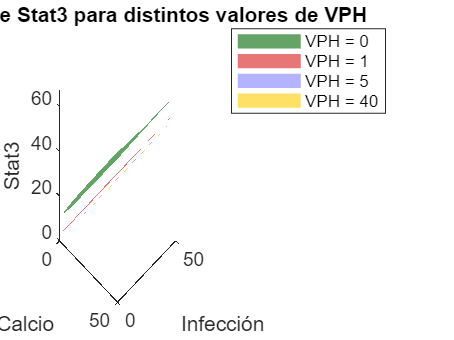

figure;
hold on;

colores = [0 0.4 0; 0.85 0.1 0.1; 0.5 0.5 1; 1 0.8 0];
leyendas = {'VPH = 0', 'VPH = 1', 'VPH = 5', 'VPH = 40'}; % ajusta si usas otros valores
h = gobjects(4,1); % para almacenar los handles
for k = 1:4
    h(k) = surf(Ca_grid, Inf_grid, grids{2}{k}, ...
                'EdgeColor', 'none', ...
                'FaceColor', colores(k,:), ...
                'FaceAlpha', 0.6);
end

view(45, 30);
xlabel('Calcio'); ylabel('Infección'); zlabel('Stat3');
title('Superficies de Stat3 para distintos valores de VPH');
legend(h, leyendas, 'Location', 'northeastoutside'); % leyenda externa al gráfico

## Coordenada de Np63

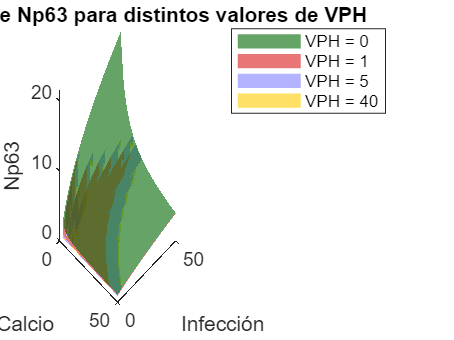

figure;
hold on;

colores = [0 0.4 0; 0.85 0.1 0.1; 0.5 0.5 1; 1 0.8 0];
leyendas = {'VPH = 0', 'VPH = 1', 'VPH = 5', 'VPH = 40'}; % ajusta si usas otros valores
h = gobjects(4,1); % para almacenar los handles
for k = 1:4
    h(k) = surf(Ca_grid, Inf_grid, grids{3}{k}, ...
                'EdgeColor', 'none', ...
                'FaceColor', colores(k,:), ...
                'FaceAlpha', 0.6);
end

view(45, 30);
xlabel('Calcio'); ylabel('Infección'); zlabel('Np63');
title('Superficies de Np63 para distintos valores de VPH');
legend(h, leyendas, 'Location', 'northeastoutside'); % leyenda externa al gráfico